**FYP-Alexnet Image Classification**

% Clearing workspace
clc
clear all
close all

% Setting folder directory dividing training data and validation data
matlabpath='C:\Users\jason\Desktop\TrainingData'

matlabpath = 'C:\Users\jason\Desktop\TrainingData'

data=fullfile(matlabpath,'AggresiveScreening/')

data = 'C:\Users\jason\Desktop\TrainingData\AggresiveScreening\'

imds=imageDatastore(data,'IncludeSubfolders',true,'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\TrainingData\AggresiveScreening\tree1\Cinnamomum_camphora0_output.png';
                              ' ...\AggresiveScreening\tree1\Cinnamomum_camphora100_output.png';
                              ' ...\AggresiveScreening\tree1\Cinnamomum_camphora102_output.png'
                               ... and 461 more
                              }
                     Folders: {
                              'C:\Users\jason\Desktop\TrainingData\AggresiveScreening'
                              }
                      Labels: [tree1; tree1; tree1 ... and 461 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreI

[imdsTrain,imdsValidation]=splitEachLabel(imds,0.7,'randomized')

imdsTrain =   ImageDatastore with properties:

                       Files: {
                              ' ...\AggresiveScreening\tree1\Cinnamomum_camphora102_output.png';
                              ' ...\AggresiveScreening\tree1\Cinnamomum_camphora104_output.png';
                              ' ...\AggresiveScreening\tree1\Cinnamomum_camphora105_output.png'
                               ... and 322 more
                              }
                     Folders: {
                              'C:\Users\jason\Desktop\TrainingData\AggresiveScreening'
                              }
                      Labels: [tree1; tree1; tree1 ... and 322 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


imdsValidation =   ImageDatastore with properties:

                       Files: {
                              ' ...\TrainingData\AggresiveScreening\tree1\Cinnamomum_camphora0_output.png';
                              ' ...\AggresiveScreening\tree1\Cinnamomum_camphora100_output.png';
                              ' ...\AggresiveScreening\tree1\Cinnamomum_camphora103_output.png'
                               ... and 136 more
                              }
                     Folders: {
                              'C:\Users\jason\Desktop\TrainingData\AggresiveScreening'
                              }
                      Labels: [tree1; tree1; tree1 ... and 136 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @read

% Selecting pre-trained network and changing final three layers with our
% classfication scheme
net = alexnet;
inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


layersTransfer = net.Layers(1:end-3);
numClasses = numel(categories(imdsTrain.Labels))

numClasses = 4

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses)
    softmaxLayer()
    classificationLayer()];

% Dataset Augmentation
Angle=[-45 45]

Angle =    -45    45


imageAugmenter=imageDataAugmenter('RandXReflection',true, ...
    'RandRotation',Angle)

imageAugmenter =   imageDataAugmenter with properties:

           FillValue: 0
     RandXReflection: 1
     RandYReflection: 0
        RandRotation: [-45 45]
           RandScale: [1 1]
          RandXScale: [1 1]
          RandYScale: [1 1]
          RandXShear: [0 0]
          RandYShear: [0 0]
    RandXTranslation: [0 0]
    RandYTranslation: [0 0]


augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

% Setting training option
options = trainingOptions('sgdm', ...
    'MiniBatchSize',16, ...
    'MaxEpochs',50, ...
    'InitialLearnRate',0.0001, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',10, ...
    'Verbose',false, ...
     'Plots','training-progress');

% Training network
netTransfer = trainNetwork(augimdsTrain,layers,options);

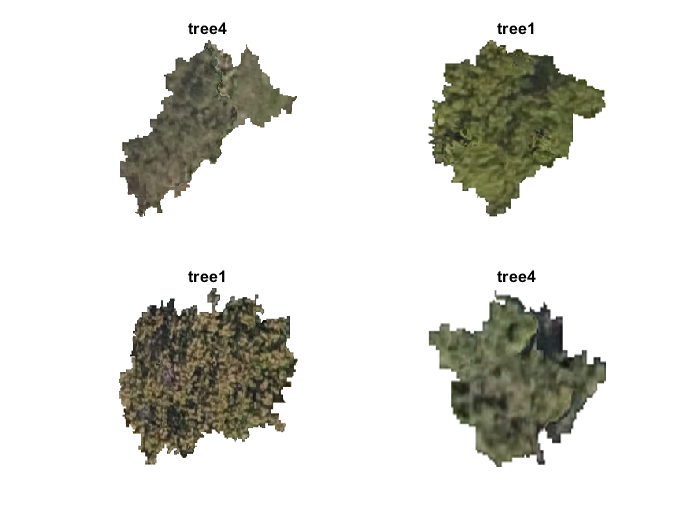

% Creating confusion matrix using the validation dataset
[YPred,scores] = classify(netTransfer,imdsValidation);
idx = randperm(numel(imdsValidation.Files));
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.9065

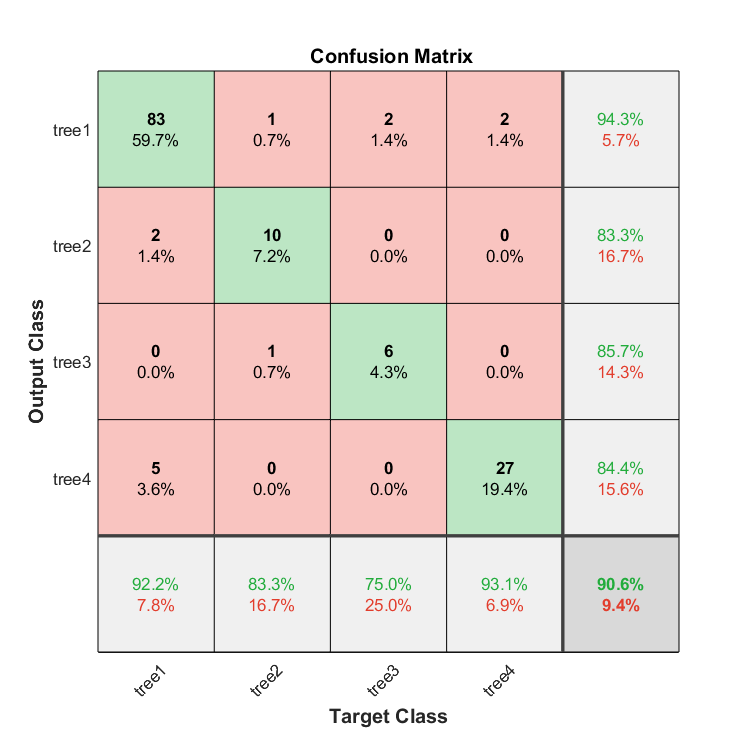

cm =   Figure (PLOTCONFUSION1) with properties:

      Number: 3
        Name: 'Confusion (plotconfusion)'
       Color: [1 1 1]
    Position: [468 132 600 600]
       Units: 'pixels'

  Show all properties


cm=plotconfusion(YValidation,YPred)

[x1,y1,T1,AUC1,OPTROCPT1]=perfcurve(YValidation,scores(:,1),'tree1')

x1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y1 =          0
    0.0111
    0.0222
    0.0333
    0.0444
    0.0556
    0.0667
    0.0778
    0.0889
    0.1000


T1 =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


AUC1 = 0.9773

OPTROCPT1 =     0.0408    0.9111


[x2,y2,T2,AUC2,OPTROCPT2]=perfcurve(YValidation,scores(:,2),'tree2')

x2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y2 =          0
    0.0833
    0.1667
    0.2500
    0.3333
    0.4167
    0.5000
    0.5833
    0.6667
    0.7500


T2 =     0.9908
    0.9908
    0.9755
    0.9723
    0.9372
    0.9314
    0.8520
    0.7302
    0.6196
    0.6130


AUC2 = 0.9941

OPTROCPT2 =          0    0.7500


[x3,y3,T3,AUC3,OPTROCPT3]=perfcurve(YValidation,scores(:,3),'tree3')

x3 =          0
         0
         0
         0
         0
    0.0076
    0.0076
    0.0076
    0.0153
    0.0229


y3 =          0
    0.1250
    0.2500
    0.3750
    0.5000
    0.5000
    0.6250
    0.7500
    0.7500
    0.7500


T3 =     0.9996
    0.9996
    0.9992
    0.9708
    0.9545
    0.7577
    0.6517
    0.5825
    0.3591
    0.1888


AUC3 = 0.9437

OPTROCPT3 =     0.0076    0.7500


[x4,y4,T4,AUC4,OPTROCPT4]=perfcurve(YValidation,scores(:,4),'tree4')

x4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y4 =          0
    0.0345
    0.0690
    0.1034
    0.1379
    0.1724
    0.2069
    0.2414
    0.2759
    0.3103


T4 =     0.9997
    0.9997
    0.9997
    0.9995
    0.9994
    0.9980
    0.9974
    0.9967
    0.9967
    0.9963


AUC4 = 0.9944

OPTROCPT4 =     0.0091    0.8966


Error using perfcurve>preparedata (line 1282)
The size of scores does not match the size of labels.

Error in perfcurve (line 393)
[scores,cls,weights,ncv] = preparedata(scores,cls,weights);

x=[0,0.5,1]
y=x

% ROC for tree 1
diffscore = scores(:,1) - scores(:,2);
diffscore1 = scores(:,1) - scores(:,3);
diffscore2 = scores(:,1) - scores(:,4);
[x5,y5,T5,AUC5,OPTROCPT5]=perfcurve(YValidation,diffscore,'tree1','negClass','tree2')

x5 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y5 =          0
    0.0111
    0.0222
    0.0333
    0.0444
    0.0556
    0.0667
    0.0778
    0.0889
    0.1000


T5 =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


AUC5 = 0.9880

OPTROCPT5 =     0.0833    0.9778


[x6,y6,T6,AUC6,OPTROCPT6]=perfcurve(YValidation,diffscore1,'tree1','negClass','tree3')

x6 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y6 =          0
    0.0111
    0.0222
    0.0333
    0.0444
    0.0556
    0.0667
    0.0778
    0.1000
    0.1111


T6 =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


AUC6 = 0.9472

OPTROCPT6 =     0.2500    1.0000


[x7,y7,T7,AUC7,OPTROCPT7]=perfcurve(YValidation,diffscore2,'tree1','negClass','tree4')

x7 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y7 =          0
    0.0111
    0.0222
    0.0333
    0.0444
    0.0556
    0.0667
    0.0778
    0.0889
    0.1000


T7 =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


AUC7 = 0.9916

OPTROCPT7 =     0.1034    0.9889


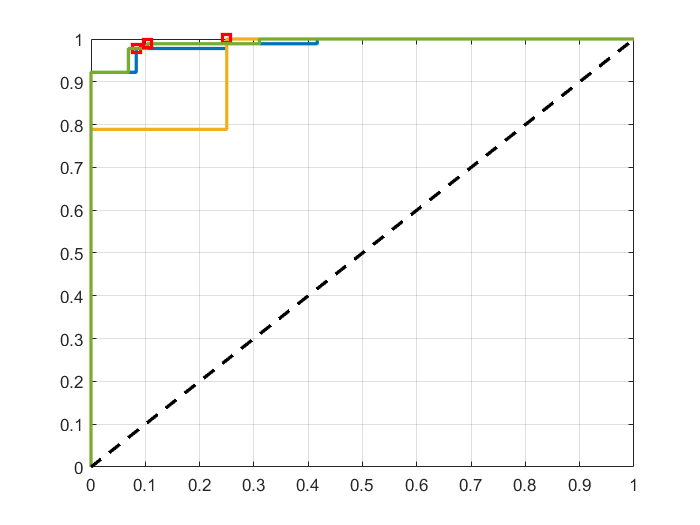

plot(x5,y5,'linewidth',2)
hold on
plot(OPTROCPT5(1),OPTROCPT5(2),'rs','linewidth',2)
plot(x6,y6,'linewidth',2)
plot(OPTROCPT6(1),OPTROCPT6(2),'rs','linewidth',2)
plot(x7,y7,'linewidth',2)
plot(OPTROCPT7(1),OPTROCPT7(2),'rs','linewidth',2)
plot(x,y,'k--','linewidth',2)
hold off
grid on

% ROC for tree 2
diffscore3 = scores(:,2) - scores(:,1);
diffscore4 = scores(:,2) - scores(:,3);
diffscore5 = scores(:,2) - scores(:,4);
[x8,y8,T8,AUC8,OPTROCPT8]=perfcurve(YValidation,diffscore3,'tree2','negClass','tree1')

x8 =          0
         0
         0
         0
         0
         0
         0
         0
    0.0111
    0.0111


y8 =          0
    0.0833
    0.1667
    0.2500
    0.3333
    0.4167
    0.5000
    0.5833
    0.5833
    0.6667


T8 =     0.9868
    0.9868
    0.9678
    0.9595
    0.9226
    0.8984
    0.7304
    0.6607
    0.5767
    0.2983


AUC8 = 0.9880

OPTROCPT8 =     0.0222    0.9167


[x9,y9,T9,AUC9,OPTROCPT9]=perfcurve(YValidation,diffscore4,'tree2','negClass','tree3')

x9 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y9 =          0
    0.0833
    0.1667
    0.2500
    0.3333
    0.4167
    0.5000
    0.5833
    0.6667
    0.7500


T9 =     0.9863
    0.9863
    0.9617
    0.9604
    0.9179
    0.8732
    0.8459
    0.5985
    0.5880
    0.5414


AUC9 = 0.9583

OPTROCPT9 =          0    0.9167


[x10,y10,T10,AUC10,OPTROCPT10]=perfcurve(YValidation,diffscore5,'tree2','negClass','tree4')

x10 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y10 =          0
    0.0833
    0.1667
    0.2500
    0.3333
    0.4167
    0.5000
    0.5833
    0.6667
    0.7500


T10 =     0.9902
    0.9902
    0.9724
    0.9692
    0.9325
    0.9297
    0.8318
    0.7185
    0.6109
    0.5552


AUC10 = 1

OPTROCPT10 =      0     1


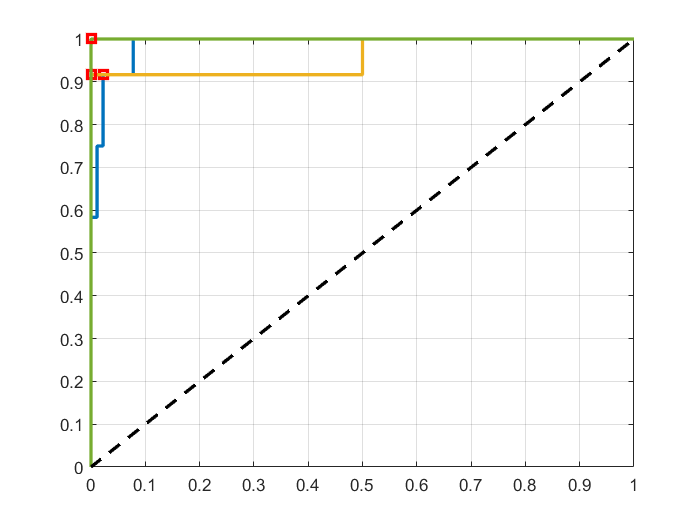

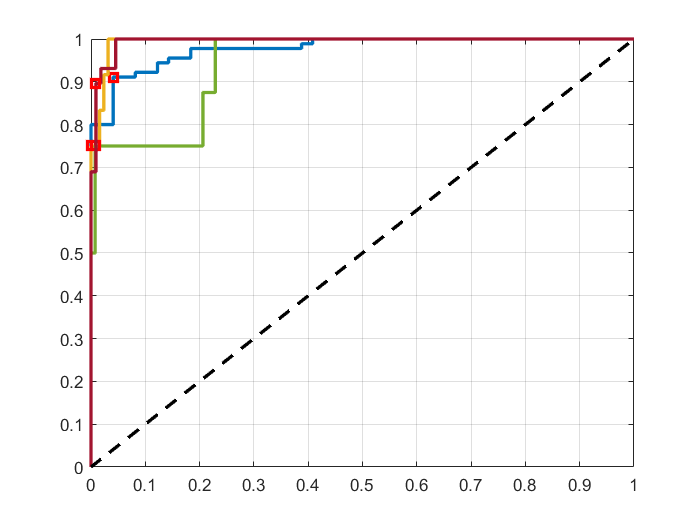

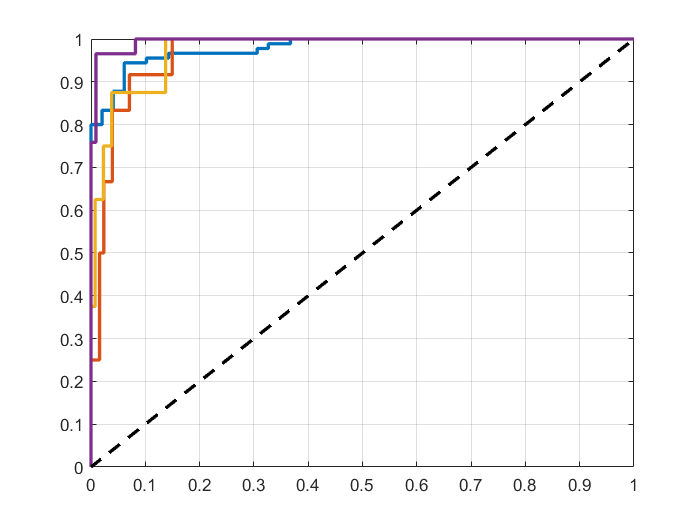

plot(x8,y8,'linewidth',2)
hold on
plot(OPTROCPT8(1),OPTROCPT8(2),'rs','linewidth',2)
plot(x9,y9,'linewidth',2)
plot(OPTROCPT9(1),OPTROCPT9(2),'rs','linewidth',2)
plot(x10,y10,'linewidth',2)
plot(OPTROCPT10(1),OPTROCPT10(2),'rs','linewidth',2)
plot(x,y,'k--','linewidth',2)
hold off
grid on

%Check MG25(Tree2)
X=imread("Pinus_thunbergii64_output.png")

X = 227×227×3 uint8 array
X(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255  

[classfn,score]= classify(netTransfer,X)

classfn = categorical
     tree4 


score = 1×4 single row vector
    0.1550    0.0003    0.0003    0.8444


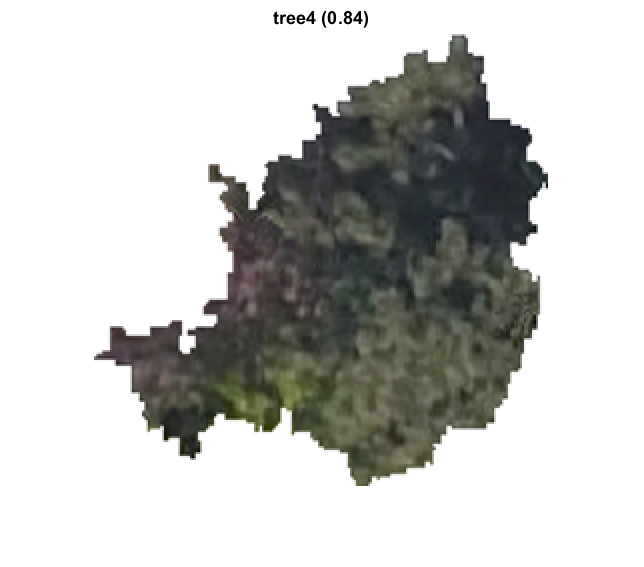

[scores, classIdx] = max(score);
imshow(X);
title(sprintf("%s (%.2f)",classfn,scores));

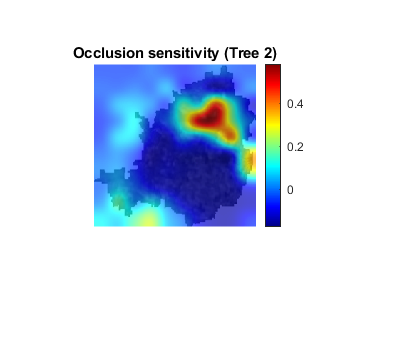

scoreMap = occlusionSensitivity(netTransfer,X,classfn);
figure
imshow(X)

hold off
hold on
imagesc(scoreMap,'AlphaData',0.7);
colormap jet
colorbar

title(sprintf("Occlusion sensitivity (Tree 2)", ...
    YPred))

LimeMap = imageLIME(netTransfer,X,classfn);

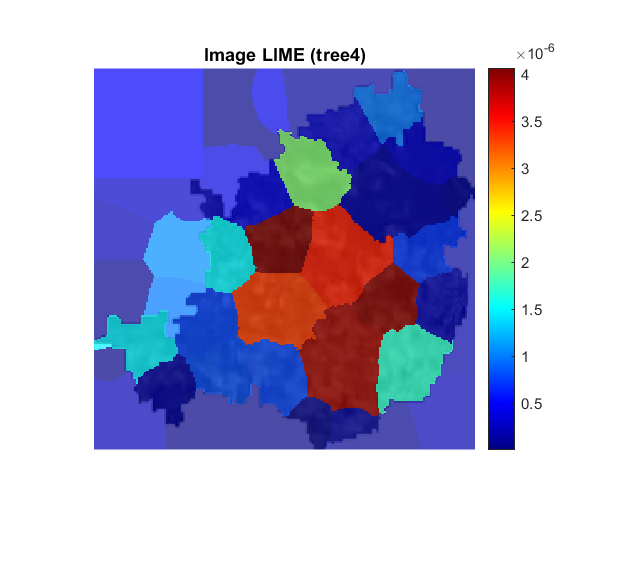

figure
imshow(X,'InitialMagnification',200)
hold on
imagesc(LimeMap,'AlphaData',0.7)
colormap jet
colorbar

title(sprintf("Image LIME (%s)", ...
    classfn))
hold off

GradientLime = imageLIME(netTransfer,X,classfn, ...
    "Segmentation","grid",...
    "OutputUpsampling","bicubic",...
    "NumFeatures",100,...
    "NumSamples",6000,...
    "Model","linear");

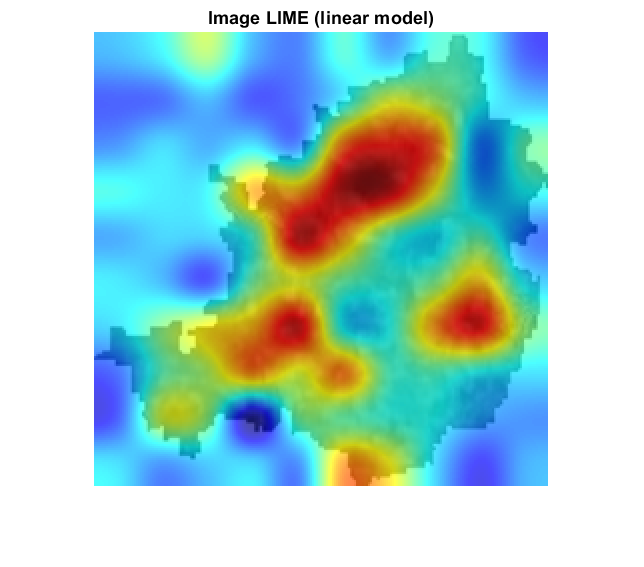

imshow(X,'InitialMagnification', 150)
hold on
imagesc(GradientLime,'AlphaData',0.7)
colormap jet

title("Image LIME (linear model)")
hold off

% Fully connected layer visualization
layer3 = 23;
name3 = netTransfer.Layers(layer3).Name

name3 = 'fc'

channels2 = 1:4;
netTransfer.Layers(end).Classes(channels2)

ans = 4×1 categorical array
     tree1 
     tree2 
     tree3 
     tree4 


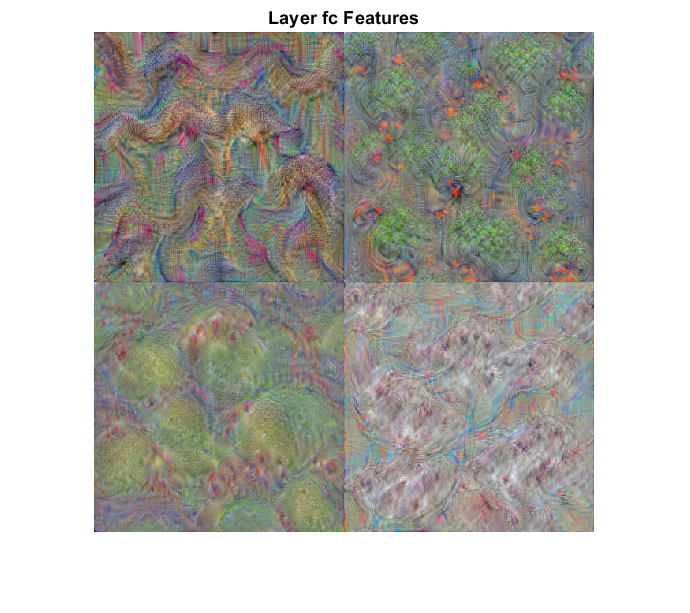

Fullycon = deepDreamImage(netTransfer,name3,channels2, ...
    'Verbose',false, ...
    'NumIterations',100, ...
    'PyramidLevels',2);
figure
Fullyconfig = imtile(Fullycon,'ThumbnailSize',[250 250]);
imshow(Fullyconfig)
title(['Layer ',name3,' Features'])